% Daten einlesen und in Variablen aufteilen
[spec, firstWordsList, wavelengths] = NIR_vorbereiten("G:\Meine Ablage\Master\02_research\Masterarbeit\04_Daten\Trainingsdatensatz");

% Initialisierung Array fuer Indizes
idxArray = zeros(size(firstWordsList));
% Setzen der Indizes pro Material
idxArray(strcmp(firstWordsList, 'HDPE')) = 1;
idxArray(strcmp(firstWordsList, 'LDPE')) = 2;
idxArray(strcmp(firstWordsList, 'PET')) = 3;
idxArray(strcmp(firstWordsList, 'PP')) = 4;
idxArray(strcmp(firstWordsList, 'PS')) = 5;
% Spektrum und Indexarray definieren
allSpectra2D = spec';
indexArray = idxArray';

% Zentrale Wellenlaengen der Filter
filter_wl =  [1150, 1200, 1250, 1400]; 
% Standardmäßige Initialisierung der Halbwertsbreiten
fwhm_values = ones(size(filter_wl)) * 10;
%Fuer benutzerdefinierte fwhm
%fwhm_values = [10,10,12,12];

% Bereiche der Filter initiieren
filter_regions = zeros(length(filter_wl), 2);

for i = 1:length(filter_wl)
    fwhm = fwhm_values(i); % Abrufen der entsprechenden Halbwertsbreite für den aktuellen Filter
    hbf = fwhm / 2;

    filter_regions(i,1) = filter_wl(i) -hbf;
    filter_regions(i,2) = filter_wl(i) +hbf;
end

integral_values = zeros(size(allSpectra2D,1), length(filter_regions));
ymin = inf;
ymax = -inf;

% Iteriere durch alle Spektren
for i = 1:size(allSpectra2D,1)
    df = allSpectra2D(i,:);
    ymin = min(ymin, min(df));
    ymax = max(ymax, max(df));

    % Funktion erstellen durch Interpolation
    interp_function = @(x) interp1(wavelengths, df, x, 'linear', 'extrap');
    % Berechnung des Integrals fuer jeden Bereich
    for j = 1:length(filter_regions)
        fun = interp_function;
        integral_values(i,j) = integral(fun, filter_regions(j,1), filter_regions(j,2));
    end
end

disp('Integralwerte für jeden Bereich:');

Integralwerte für jeden Bereich:


disp(integral_values);

    5.1186    3.8476    4.8827    4.3153
    5.1508    3.8893    4.9308    4.3728
    5.0618    3.8128    4.8279    4.2704
    5.0042    3.7641    4.7704    4.2081
    4.0697    2.7237    3.8179    3.2716
    4.1237    2.8354    3.9063    3.3945
    6.6757    4.5776    5.7865    4.4702
    7.1665    4.9470    6.2184    4.8351
    6.6452    4.5652    5.7641    4.4596
    7.1974    4.9705    6.2447    4.8552
    5.0439    3.3386    4.2948    3.1310
    5.1783    3.4834    4.4379    3.2623
    4.4054    2.5559    3.3080    1.9837
    3.5401    2.0458    2.9215    1.7216
    4.2366    2.8461    3.7693    2.6974
    6.4067    4.3667    5.5114    4.1453
    6.8253    4.4716    5.7813    4.2771
    6.5711    4.6152    5.7181    4.3694
    6.4470    4.3722    5.5313    4.1480
    5.3229    3.6847    4.6114    3.4582
    5.4402    3.8618    4.7514    3.6149
    5.5268    3.8443    4.7935    3.6034
    5.6881    4.0000    4.9514    3.7457
    7.6638    7.0717    7.5560    7.3076
    8.7890    8.

latent =     1.0486
    0.3771
    0.0427
    0.0000


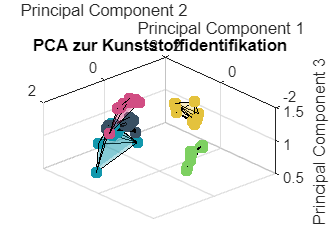

% Durchfuehrung der PCA
[coeff, X_pca, y, convHull,  X_pca_per_class, T] = pca_analysis_triangulation(integral_values, indexArray);